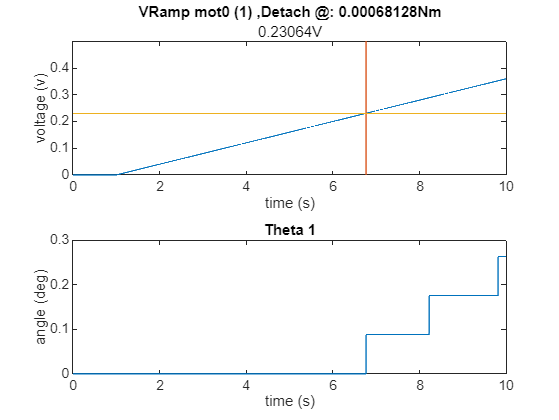

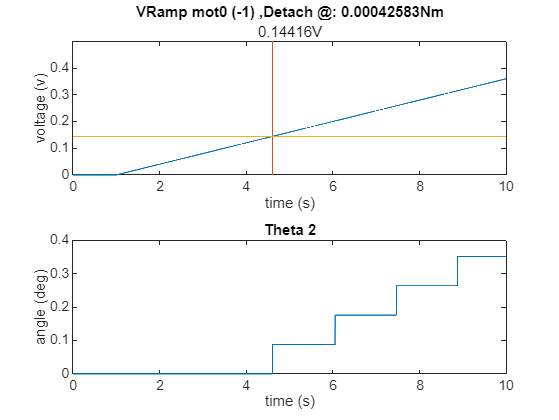

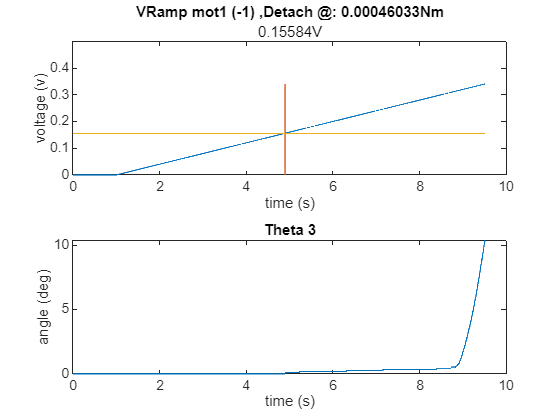

filelist = ["data_21-Mar-2025_20 deadzone mot0 pos.mat", 
    "data_21-Mar-2025_20 deadzone motor0 neg.mat" ,
    % "data_21-Mar-2025_10 deazone mot1 pos.mat",
    "data_21-Mar-2025_20 deadzone mot1 neg.mat"];
% exp_id = 1
Km = 7.68e-3; % V/(rad/s)
Ra = 2.6;

for exp_id = 1:3
    filename = "lab3/data/" + filelist(exp_id);
    load(filename,"data");
    
    motorIDs = [0 0  1];
    motorDir = [ 1 -1  -1];
    motorId = motorIDs(exp_id);
    
    
    t = data(1,:);
    y = abs(rad2deg(data(2+motorId,:)*pi/2048));
    u = abs(data(4+motorId,:));
    % figure
    % plot(t,u)
    % figure
    % plot(t,y)
    
    k = find(y); % finds the non-zero elements
    t_detach =  t(k(1));
    u_detach = u(k(1));
    torque_stick = u_detach * Km / Ra;
    
    figure
    subplot(2,1,1)
    plot(t,u)
    ylim([0 0.5])
    xlim([0 10])
    title("VRamp mot"+motorId + " ("+motorDir(exp_id)+") ," + "Detach @: " +torque_stick +"Nm")
    subtitle( u_detach +"V")

    ylabel("voltage (v)")
    xlabel("time (s)")
    hold on
    plot([t_detach t_detach],[0 max(u)])
    plot([0 max(t)],[u_detach u_detach])
    hold off
    
    
    subplot(2,1,2)
    plot(t,y)
    % ylim([0 0.5])
    xlim([0 10])
    title("Theta "+exp_id)
    xlabel("time (s)")
    ylabel("angle (deg)")
end